% This script is for loading and processing camera data from the HMT
clear; close all; clc;
 
% Load camera data file from HMT
HMT_file_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_05_27_01_HX200_Final_Relay_2DBM_V2/AS-2025052701-S1 Cam Diffracted LowExposure.mat";
HMT_CAM_DATA = loadAndSortCamData(HMT_file_directory); %clear("HMT_file_directory");

function [HMT_CAM_DATA] = loadAndSortCamData(HMT_file_directory)
    % Function to load HMT angle scan camera data and sort beams
    % Load data file from experiment
    load(HMT_file_directory);
    HMT_CAM_DATA.Hom_Out.HMT_Directory = HMT_file_directory;

    % Check if beam struct is defined yet
    if isfield(HMT_CAM_DATA,'In_Data') == 1
        % If object beam, make S_Beam struct
        if HMT_CAM_DATA.In_Data.Beam_Type == 'OBJ'
            % Insert new s-beam field
            HMT_CAM_DATA.S_Beam = HMT_CAM_DATA;

            % Remove previous fields
            HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "In_Data");
            HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "AS_Cam");
            HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "Hom_Out");
        else
        end
        % If reference beam, make R_Beam struct
    elseif HMT_CAM_DATA.In_Data.Beam_Type == 'REF'
        % Insert new r-beam field
        HMT_CAM_DATA.R_Beam = HMT_CAM_DATA;

        % Remove previous fields
        HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "In_Data");
        HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "AS_Cam");
        HMT_CAM_DATA = rmfield(HMT_CAM_DATA, "Hom_Out");
    else
        disp('Beams already sorted for this file')
    end
end

Cam_B = HMT_CAM_DATA.S_Beam; % Choose one beam for now, figure out how to do the rest later

% Define test range and plot the data overview:
% Create an array of test angles to subsample
Cam_B.Hom_Out.Num_Angles  = 7; % Symmetric about bisector
 

% Check test images from HMT scan for one side
[Cam_B.Hom_Out.Test_Images, Cam_B.Hom_Out.Test_Angles] = checkTestImages(Cam_B);

% Re-working the homography control point calibration code
test_images = Cam_B.Hom_Out.Test_Images;
test_angles = Cam_B.Hom_Out.Test_Angles;

prime_angle = 22; % 22 degree external Bragg angle

num_images = Cam_B.Hom_Out.Num_Angles;

% Manual control point referencing - 22Deg ref w/ +- 30 degrees about Bragg
% at -45 - OBJECT side beam
test_idx = 1;
test_cal_image = test_images{test_idx};
imagesc(test_cal_image); title(sprintf('Image %d / 7',test_idx));



% Control points
cal_NW = flip([505,314; 505,315; 515,316; 527,317; 557,318; 585,319; 614,319;]);
cal_NE = flip([1022,317; 1019,316; 1007,315; 992,316; 968,316; 949,316; 921,315;]);
cal_SE = flip([1026,835; 1021,834; 1011,833; 996,832; 976,832; 952,831; 925,830;]);
cal_SW = flip([511,833; 511,833; 516,835; 536,834; 554,831; 588,833; 620,831;]);

% Organize data
NW_x = cal_NW(:,1); NW_y = cal_NW(:,2);
NE_x = cal_NE(:,1); NE_y = cal_NE(:,2);
SE_x = cal_SE(:,1); SE_y = cal_SE(:,2);
SW_x = cal_SW(:,1); SW_y = cal_SW(:,2);

% Plots to see trends and check for errors
% figure;
% plot(NW_y, NW_x,'b*'); grid on; title('NW');
% plot(NE_y, NE_x,'r*'); grid on; title('NE');
% plot(SE_y, SE_x,'m*'); grid on; title('SE');
% plot(SW_y, SW_x,'k*'); grid on; title('SW');

tiledlayout(1,2)
nexttile
plot(test_angles,NW_x,'o');
grid on;
% xlabel('Angle Range (deg)'); ylabel('x px Location');
nexttile
plot(test_angles,NW_y,'^');
grid on;
% xlabel('Angle Range (deg)'); ylabel('7 px Location')

% % Manual referencing v4 - % 20 deg ref w/ +- 35 degrees - OBJECT
% % test_images = Cam_B.Hom_Out.Test_Images;
% % test_angles = Cam_B.Hom_Out.Test_Angles;
% % 
% % i_image = 7;
% % figure;
% % imshow(test_images{1, i_image});
% 
% 
% % Control points
% cal_NW = [306,126; 292,126; 289,127; 295,127; 310,127; 332,127; 360,127; ];
% cal_NE = [1132,114; 1132,115; 1122,114; 1098,114; 1064,115; 1016,114; 958,114; ];
% cal_SE = [1145,952; 1145,952; 1133,952; 1109,951; 1073,952; 1024,951; 965,953; ];
% cal_SW = [320,967; 307,967; 304,967; 308,967; 322,968; 343,966; 370,965];
% 
% % Organize data
% NW_x = cal_NW(:,1); NW_y = cal_NW(:,2);
% NE_x = cal_NE(:,1); NE_y = cal_NE(:,2);
% SE_x = cal_SE(:,1); SE_y = cal_SE(:,2);
% SW_x = cal_SW(:,1); SW_y = cal_SW(:,2);
% 
% % Plots to see trends and check for errors
% figure;
% plot(NW_y, NW_x,'b*'); grid on; title('NW');
% plot(NE_y, NE_x,'r*'); grid on; title('NE');
% plot(SE_y, SE_x,'m*'); grid on; title('SE');
% plot(SW_y, SW_x,'k*'); grid on; title('SW');
% 
% tiledlayout(1,2)
% nexttile
% plot(test_angles,SW_x,'o');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('x px Location');
% nexttile
% plot(test_angles,SW_y,'^');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('7 px Location')

% Perform homography image correction:
 
Cam_B.Hom_Out.Hom_Image_Data = performHomography(Cam_B);

% Reassign beam processing to HMT structure
HMT_CAM_DATA.S_Beam = Cam_B; clear("Cam_B");

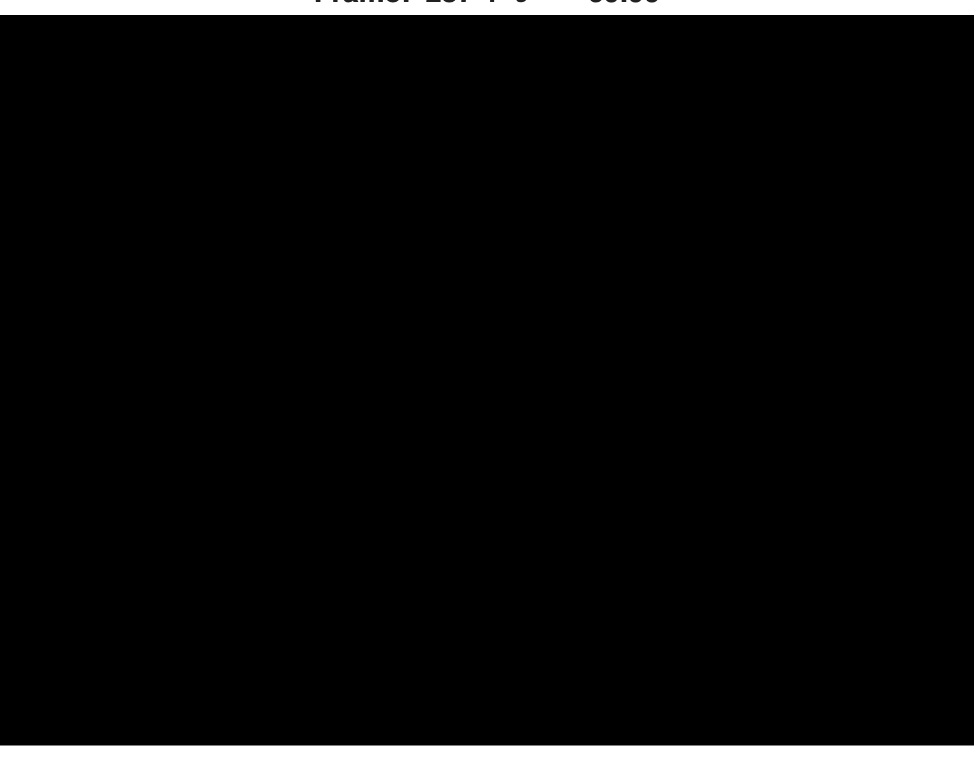

% Play the angle scan video (optional):
% Plot the uncorrected angle scan video
 
vid_image_data = HMT_CAM_DATA.S_Beam.AS_Cam.Image_Data;
vid_angle_data = HMT_CAM_DATA.S_Beam.AS_Cam.Angle_Data;
fps = 30; frame_skip = 2;
playAngleScanVideoWithOptions(vid_image_data, vid_angle_data, fps, frame_skip);

clear("vid_image_data","vid_angle_data","fps","frame_skip");

% Play video of corrected image (Optional):
% R-beam corrected angle scan video
 
vid_image_data = HMT_CAM_DATA.S_Beam.Hom_Out.Hom_Image_Data;
vid_angle_data = HMT_CAM_DATA.S_Beam.AS_Cam.Angle_Data;
fps = 30; frame_skip = 2;
playAngleScanVideoWithOptions(vid_image_data, vid_angle_data, fps, frame_skip);
clear("vid_image_data","vid_angle_data","fps","frame_skip");

% OPTIONAL play uncorrected and corrected side by side
 
vid_image_data_uncorrected = HMT_CAM_DATA.S_Beam.AS_Cam.Image_Data;
vid_image_data_corrected   = HMT_CAM_DATA.S_Beam.Hom_Out.Hom_Image_Data;
vid_angle_data             = HMT_CAM_DATA.S_Beam.AS_Cam.Angle_Data;
playAngleScanSideBySide(vid_image_data_corrected, vid_image_data_uncorrected, vid_angle_data);
clear('vid_image_data_corrected',"vid_image_data_uncorrected","vid_angle_data");

% Save the homographically corrected data
save(HMT_file_directory,"HMT_CAM_DATA")
disp('Corrected Data saved!');

Corrected Data saved!


Move forward with corrected image data!

% Now load the homographically corrected data
clear; close all; clc;
hom_data_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_05_27_01_HX200_Final_Relay_2DBM_V2/AS-2025052701-S1 Cam Diffracted LowExposure.mat";
load(hom_data_directory);
disp('Corrected Data Loaded')

Corrected Data Loaded


% Test plot the loaded data
 
vid_image_data = HMT_CAM_DATA.S_Beam.Hom_Out.Hom_Image_Data;
vid_angle_data = HMT_CAM_DATA.S_Beam.AS_Cam.Angle_Data;
fps = 30; frame_skip = 1;
playAngleScanVideoWithOptions(vid_image_data, vid_angle_data, fps, frame_skip);
clear("vid_image_data","vid_angle_data","fps","frame_skip");

% Now start the post-processing steps in preparation for fitting

function [image_data_hom] = performHomography(DATA_In)
    % Function to perform homography on beam cam data
    % Determine beam type for calibration
    type = DATA_In.In_Data.Beam_Type;

    % Load the calibration functions
    CAL = loadCalibrationFunctions(type);

    % Parse input data
    image_data = DATA_In.AS_Cam.Image_Data;
    angle_data = DATA_In.AS_Cam.Angle_Data;

    % Get data size
    num_frames = size(image_data, 2);

    % Assign REF functions
    NW_X_Fit = CAL.NW.X; NW_Y_Fit = CAL.NW.Y;
    NE_X_Fit = CAL.NE.X; NE_Y_Fit = CAL.NE.Y;
    SE_X_Fit = CAL.SE.X; SE_Y_Fit = CAL.SE.Y;
    SW_X_Fit = CAL.SW.X; SW_Y_Fit = CAL.SW.Y;

    % Assign homography reference index based on beam
    if type == 'REF'
        idx_ref = 1;
    elseif type == 'OBJ'
        idx_ref = num_frames;
    else
    end

    % Assign homgraphy reference angle
    angle_ref = angle_data(idx_ref);

    % Assign homography reference image
    image_ref = image_data{idx_ref};

    % Generic reference angle
    reference_angle = angle_ref;  % Reference Angle for Homography

    % Generic reference image
    reference_image = image_ref;  % Reference Image for Homography

    % Use fxn to get reference coords
    NW_Coords = [NW_X_Fit(reference_angle), NW_Y_Fit(reference_angle)];
    NE_Coords = [NE_X_Fit(reference_angle), NE_Y_Fit(reference_angle)];
    SE_Coords = [SE_X_Fit(reference_angle), SE_Y_Fit(reference_angle)];
    SW_Coords = [SW_X_Fit(reference_angle), SW_Y_Fit(reference_angle)];

    % Make reference points block
    reference_coords = [NW_Coords; NE_Coords; SE_Coords; SW_Coords];

    % Loop through angle scan data and apply control point corrections
    for i_frames = 1:num_frames
        distorted_img = image_data{i_frames};    % Image taken at an angle theta
        fit_angle     = angle_data(i_frames);    % Angle theta for this frame

        % Use fxn to get distortion coords
        NW_dis = [NW_X_Fit(fit_angle), NW_Y_Fit(fit_angle)];
        NE_dis = [NE_X_Fit(fit_angle), NE_Y_Fit(fit_angle)];
        SE_dis = [SE_X_Fit(fit_angle), SE_Y_Fit(fit_angle)];
        SW_dis = [SW_X_Fit(fit_angle), SW_Y_Fit(fit_angle)];

        % Make distortion points block
        distorted_coords = [NW_dis; NE_dis; SE_dis; SW_dis];

        % Compute projective transformation (homography)
        tform = fitgeotrans(distorted_coords, reference_coords, 'projective');

        % Warp the distorted image to match the reference view
        output_view   = imref2d(size(reference_image));  % Output image has same size as reference
        corrected_img = imwarp(distorted_img, tform, 'OutputView', output_view);

        image_data_hom{1, i_frames} = corrected_img; % Assign image
    end
end

function [CAL] = loadCalibrationFunctions(type)
    % Function to load in the calibration functions for homography
    % Assign type for ref vs obj

    if type == 'REF'
        load("HMT_Cam_CalFxns_32D.mat","NE_X_REF_Fxn","NE_Y_REF_Fxn",'NW_X_REF_Fxn','NW_Y_REF_Fxn','SE_X_REF_Fxn','SE_Y_REF_Fxn','SW_X_REF_Fxn','SW_Y_REF_Fxn');
        % Build convenient structure for cal files
        CAL.NW.X = NW_X_REF_Fxn;
        CAL.NW.Y = NW_Y_REF_Fxn;

        CAL.NE.X = NE_X_REF_Fxn;
        CAL.NE.Y = NE_Y_REF_Fxn;

        CAL.SE.X = SE_X_REF_Fxn;
        CAL.SE.Y = SE_Y_REF_Fxn;

        CAL.SW.X = SW_X_REF_Fxn;
        CAL.SW.Y = SW_Y_REF_Fxn;
    elseif type == 'OBJ'
        load("Homography_Canon_Obj_22Deg_Fxns.mat","NW_X_Obj_Fit","NW_Y_Obj_Fit","NE_X_Obj_Fit","NE_Y_Obj_Fit","SE_X_Obj_Fit","SE_Y_Obj_Fit","SW_X_Obj_Fit","SW_Y_Obj_Fit");
        % Build convenient structure for cal files
        CAL.NW.X = NW_X_Obj_Fit;
        CAL.NW.Y = NW_Y_Obj_Fit;

        CAL.NE.X = NE_X_Obj_Fit;
        CAL.NE.Y = NE_Y_Obj_Fit;

        CAL.SE.X = SE_X_Obj_Fit;
        CAL.SE.Y = SE_Y_Obj_Fit;

        CAL.SW.X = SW_X_Obj_Fit;
        CAL.SW.Y = SW_Y_Obj_Fit;
    else
        disp('Cal function not found.. or something');
    end
end

function playAngleScanVideoWithOptions(image_data, angle_data, fps, frame_skip)
    % Function to play the angle scan videos
    % Get dimensions of video
    [~, num_frames] = size(image_data);

    % Set up figure and axes once
    h_Fig   = figure;
    h_Ax    = axes('Parent', h_Fig);
    h_Img   = imshow(image_data{1}, 'Parent', h_Ax);
    h_Title = title(h_Ax, sprintf('Frame: 1 | \\theta = %.2f', angle_data(1)));

    % Playback loop
    for i_frames = 1:frame_skip:num_frames
        % Update image
        set(h_Img, 'CData', image_data{i_frames});

        % Update title
        set(h_Title, 'String', sprintf('Frame: %i | \\theta = %.2f', i_frames, angle_data(i_frames)));

        drawnow;
        pause(1/fps);
    end
end

function [test_images, test_angles] = checkTestImages(DATA_In)
    % Function to assign test ranges to HMT cam data for one beam
    % HMT setup data
    bisector_angle = DATA_In.In_Data.Bisector_Angle_AS;
    scan_range     = DATA_In.In_Data.Scan_Range;
    num_angles     = DATA_In.Hom_Out.Num_Angles;

    % HMT output data
    angle_data = DATA_In.AS_Cam.Angle_Data; % HMT stage data absolute
    image_data = DATA_In.AS_Cam.Image_Data; % HMT signal data on camera for one beam

    image_data_mat = cell2mat(image_data); % !! Might be useful later, not sure yet.

    % Calculate angle ranges
    correction_factor = 5; % !! Needed bc HMT is not collecting the first 5 degrees
    [start_angle, stop_angle] = defineAngleRanges(bisector_angle, scan_range, correction_factor);

    % Create test angle vector
    angles_test = linspace(stop_angle, start_angle, num_angles);

    % Find the real corresponding angles and frame numbers for test data
    [angles_real, angles_real_idx] = matchClosestValues(angle_data, angles_test, num_angles);

    % Make sure the test data lines up with the real data:
    % Make figure for test angle registration
    figure;
    plot(angles_test,'ro','MarkerSize',10); hold on;
    plot(angles_real,'b*','MarkerSize',10); hold off;
    yline(bisector_angle,'c');
    grid on; title('Test Angle Registration');
    legend('Try','Hit','Bisector','location','northwest');
    xlabel('Test Angle Index'); ylabel('\theta [\circ]')

    % Plot the corresponding images to real test angles:
    % Pre-allocate test cell array
    images_real = cell(1, num_angles);

    % Pull the test images
    for i_frames = 1:num_angles
        images_real{i_frames} = image_data{angles_real_idx(i_frames)};
    end

    % Pull first, last, and middle idx for checking
    image_start_idx  = num_angles;
    image_stop_idx   = 1;
    image_center_idx = ceil(num_angles / 2);

    % Pull the corresponding images
    image_start  = images_real{image_start_idx};
    image_stop   = images_real{image_stop_idx};
    image_center = images_real{image_center_idx};

    % Make title strings
    image_start_str  = sprintf('Start Frame = %i | \\theta = %.2f\\circ', image_start_idx, angles_real(image_start_idx));
    image_stop_str   = sprintf('Stop Frame = %i | \\theta = %.2f\\circ', image_stop_idx, angles_real(image_stop_idx));
    image_center_str = sprintf('Center Frame = %i | \\theta = %.2f\\circ', image_center_idx, angles_real(image_center_idx));

    % Make figures for first, center, last test angles
    figure;
    imagesc(image_start); axis image off;
    % imshow(image_start);
    title(image_start_str);

    figure;
    imagesc(image_center); axis image off;
    % imshow(image_center);
    title(image_center_str);

    figure;
    imagesc(image_stop); axis image off;
    % imshow(image_stop);
    title(image_stop_str);

    % % Plot the three images together so we can see them all aligned
    % plotTestImagesTogether

    % Make output variables
    test_images = images_real; % Assign test image block
    test_angles = angles_real; % Assign test angles block
end

function [start_angle, stop_angle] = defineAngleRanges(bisector_angle, scan_range, correction_factor)
    % Define the stage angle ranges
    start_angle = bisector_angle + (scan_range / 2) - correction_factor;
    stop_angle  = bisector_angle - (scan_range / 2);

end

function angle_centered = shiftAngles(angle_vec, bisector_angle)
    % Center the angle stage data about the bisector (detuning)
    angle_centered = angle_vec - bisector_angle;
end

Manual calibration fitting

% % Manual referencing v4 - % 32 deg ref w/ +- 35 degrees - OBJECT
%
% % Control points
% cal_NW = [350,125; 340,126; 341,128; 352,131; 372,133; 398,136; 429,138];
% cal_NE = [1180,121; 1172,118; 1147,116; 1109,115; 1059,115; 994,115; 910,115];
% cal_SE = [1188,955; 1178,955; 1154,957; 1117,956; 1061,960; 996,961; 915,963];
% cal_SW = [354,961; 345,960; 346,960; 357,959; 375,959; 401,959; 428,958];
%
% % Organize data
% NW_x = cal_NW(:,1); NW_y = cal_NW(:,2);
% NE_x = cal_NE(:,1); NE_y = cal_NE(:,2);
% SE_x = cal_SE(:,1); SE_y = cal_SE(:,2);
% SW_x = cal_SW(:,1); SW_y = cal_SW(:,2);
%
% % Plots to see trends and check for errors
% figure;
% plot(NW_y, NW_x,'b*'); grid on; title('NW');
% plot(NE_y, NE_x,'r*'); grid on; title('NE');
% plot(SE_y, SE_x,'m*'); grid on; title('SE');
% plot(SW_y, SW_x,'k*'); grid on; title('SW');
%
% tiledlayout(1,2)
% nexttile
% plot(real_angles,SW_x,'o');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('x px Location');
% nexttile
% plot(real_angles,SW_y,'^');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('7 px Location')

% % Manual referencing v4 - % 32 deg ref w/ +- 35 degrees - REFERENCE
%
% % Control points
% cal_NW = [619,117; 543,118; 460,119; 393,120; 339,121; 299,122; 270,124];
% cal_NE = [934,135; 979,133; 1017,133; 1050,130; 1077,127; 1094,124; 1099,121];
% cal_SE = [943,957; 982,955; 1023,957; 1057,957; 1082,955; 1099,955; 1106,957];
% cal_SW = [631,969; 529,964; 450,965; 395,964; 343,965; 303,965; 275,964];
%
% % Organize data
% NW_x = cal_NW(:,1); NW_y = cal_NW(:,2);
% NE_x = cal_NE(:,1); NE_y = cal_NE(:,2);
% SE_x = cal_SE(:,1); SE_y = cal_SE(:,2);
% SW_x = cal_SW(:,1); SW_y = cal_SW(:,2);
%
% % Plots to see trends and check for errors
% figure;
% plot(NW_y, NW_x,'b*'); grid on; title('NW');
% plot(NE_y, NE_x,'r*'); grid on; title('NE');
% plot(SE_y, SE_x,'m*'); grid on; title('SE');
% plot(SW_y, SW_x,'k*'); grid on; title('SW');
%
% tiledlayout(1,2)
% nexttile
% plot(real_angles,SW_x,'o');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('x px Location');
% nexttile
% plot(real_angles,SW_y,'^');
% grid on;
% % xlabel('Angle Range (deg)'); ylabel('7 px Location')

Plot comparison video (no colormap)

% % Play both videos together simultaneously
% x_lines = 1:n_lines:2*img_height; % Make gridlines for double-wide
% figure;
% for i_frames = 1:num_frames
%     imshowpair(image_data{i_frames},image_data_hom{i_frames},'montage');
%     hold on; xline(x_lines,'r','LineWidth',1); yline(y_lines,'r','LineWidth',1); hold off;
%     title(sprintf('\\theta = %.1f° | Frame = %i', angle_data(i_frames), i_frames), 'Interpreter', 'tex');
%     pause(1/30); drawnow;
% end

Plot comparison video with colormap

% % Play both videos together simultaneously with colormap
% x_lines = 1:n_lines:2*img_height; % Make gridlines for double-wide
% figure;
% for i_frames = 1:num_frames
%     % Convert both images to RGB using your custom colormap
%     im1_rgb = ind2rgb(im2uint8(mat2gray(image_data{i_frames})), colormap(bone));
%     im2_rgb = ind2rgb(im2uint8(mat2gray(image_data_hom{i_frames})), colormap(bone));
%
%     % Show the montage
%     imshow([im1_rgb, im2_rgb]);  % concat for montage effect
%     hold on; xline(x_lines,'r','LineWidth',1); yline(y_lines,'r','LineWidth',1); hold off;
%     title(sprintf('Image Correction: \\theta = %.1f° | Frame = %i', angle_data(i_frames), i_frames), 'Interpreter', 'tex');
%     pause(1/30); drawnow;
% end

Load CORRECTED data for FITTING - OBJ Only

% Load in corrected image data
clear; close all; clc;
load_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_04_09_01_Bayfol_HX200_TVHG_Imaging/AS-25040802-T2-W-SmlThta.mat";
load(load_directory); clear('load_directory');

angle_data      = Processed_Cam.angle_data;
image_data_hom = Processed_Cam.image_data_corr;
bisector_angle  = Processed_Cam.bisector_angle;

% Get data sizes
[img_width, img_height] = size(image_data_hom{1,1});
num_frames              = size(image_data_hom,2);

% Check images
frameNum         = round(num_frames/2);
image_reference  = image_data_hom{1,frameNum};

Load CORRECTED data for FITTING - OBJ and REF

% Load in corrected image data for Obj and Ref
clear; close all; clc;
Ref_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_04_15_01_2DBM_HX200_500nm/S2/AS-25040802-S2-Cal-Ref.mat";
Obj_directory = "/Users/andrewsias_m3p/Library/CloudStorage/OneDrive-UCB-O365/Holography/Holography Directory/AS_2025_04_15_01_2DBM_HX200_500nm/S2/AS-25040802-S2-Cal-Obj.mat";
load(Ref_directory); clear("Ref_directory");
REF = Processed_Cam;
load(Obj_directory);
OBJ = Processed_Cam; clear("Obj_directory"); clear("Processed_Cam");


% Get data sizes
REF = getDataSize(REF);
OBJ = getDataSize(OBJ);

% Function for getting data sizes
function DATA = getDataSize(DATA)
    DATA.angle_data      = DATA.angle_data;
    DATA.image_data_corr = DATA.image_data_corr;
    DATA.bisector_angle  = DATA.bisector_angle;

    % Get data sizes
    [DATA.img_width, DATA.img_height] = size(DATA.image_data_corr{1,1});
    DATA.num_frames              = size(DATA.image_data_corr,2);

    % Check images
    DATA.frameNum         = round(DATA.num_frames/2);
    DATA.image_reference  = DATA.image_data_corr{1,DATA.frameNum};
end

% Spatial average videos to wash out noise
filterSize = 17;
REF = spatialAvgImages(REF, filterSize);
OBJ = spatialAvgImages(OBJ, filterSize);

% Function for spatial averaging to wash out noise
function DATA = spatialAvgImages(DATA,filterSize)
    for idx = 1:DATA.num_frames
        DATA.image_averaged{idx} = imboxfilt(DATA.image_data_corr{idx},filterSize);
    end

    DATA.average_reference = DATA.image_averaged{1,DATA.frameNum};

    figure; imshowpair(DATA.image_reference,DATA.average_reference,'montage'); colormap('parula');
    title(sprintf('Spatial Averaging: %ix%i px',filterSize,filterSize));
end

% Resize images
mag_factor = 0.5;

REF = resizeImages(REF,mag_factor);
OBJ = resizeImages(OBJ,mag_factor);

% Function to resize images
function DATA = resizeImages(DATA,mag_factor)
    for idx = 1:DATA.num_frames
        DATA.image_regions{idx} = imresize(DATA.image_averaged{idx},mag_factor);
    end

    % Get image and new sizes
    DATA.region_reference = DATA.image_regions{DATA.frameNum};
    [DATA.reg_width, DATA.reg_height] = size(DATA.region_reference);

    % Plot resolution comparison
    figure; imshow(DATA.image_reference); title(sprintf('M = 1x | %ix%i px',DATA.img_width,DATA.img_height)); colormap('parula');
    figure; imshow(DATA.region_reference); title(sprintf('M = %.1fx | %ix%i px',mag_factor,DATA.reg_width,DATA.reg_height)); colormap('parula');
end

% figure;
% for idx = 1:OBJ.num_frames
%     obj_image = REF.image_regions{idx};
%     ref_image = OBJ.image_regions{idx};
%
%     DE_image = obj_image ./ (ref_image + obj_image);
%     imagesc(DE_image); axis image off; pause(1/30); drawnow;
% end
%


Power meter readout on full image

% Perform pseudo power meter readout on full frame
DE_PM_Max = 0.89; % Max DE
REF = pseudoPM_Obj(REF, DE_PM_Max);

% Function to perform pseudo power meter readout on full frame
function DATA = pseudoPM_Obj(DATA, DE_PM_Max)
    % Integrate full-frame signal data
    for idx = 1:DATA.num_frames
        DATA.DE_PM(idx) = sum(sum(DATA.image_regions{idx}));
    end

    % Remove offsets and calibrate to PM readout

    DATA.DE_PM = DATA.DE_PM - min(DATA.DE_PM);                 % Remove zero offset
    DATA.DE_PM = (DATA.DE_PM ./ max(DATA.DE_PM)) .* DE_PM_Max; % Normalize to PM

    % Set angle data about bisector angle for CWT fitting
    DATA.angleCWT = DATA.angle_data - DATA.bisector_angle;

    % Plot pseudo-PM DE signal
    figure; plot(DATA.angleCWT,DATA.DE_PM,'r.'); xline(0,'k');
    title('Pseudo Power Meter Readout')
    xlabel('\Delta\theta_{0} [{\circ}]'); ylabel('\eta'); grid on;
    xlim([-20 20]); ylim([0 1]);
end

% Fit "power meter" to CWT - USE MATERIAL ANGLE:
angleCWT = REF.angleCWT;
DE_PM = REF.DE_PM;

plot_title = char('Pseudo Power Meter Readout');
[OUT.CWT.in , OUT.CWT.out] = FitBraggSelectivity(angleCWT,DE_PM, ...
    'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
    'RefWrtTheta', -20.7,'ObjWrtTheta', 20.7, ...
    'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 532E-09, 'lambdaRed0', 532E-09, ...
    'L0', 16E-6,'n10', 10E-03, ...
    'Born'   , false, ...
    'PlotTitle', plot_title);
axis([-20 20 0 1]);

% Save figure for re-plotting
saveas(gcf,convertCharsToStrings(plot_title));

NORMALIZE Bragg-letts for CWT fitting

% Function to find max count to scale DE to
for i_frames = 1:REF.num_frames
    REF.img_max(i_frames) = max(max(REF.image_regions{i_frames}));
end

REF.globeMax = max(REF.img_max); % Global cout max to scale to

% Loop through images and pull out pixel Bragg curves

REF.image_pixels = zeros(REF.reg_width, REF.reg_height, REF.num_frames, 'uint16');

for i_frames = 1:REF.num_frames
    REF.image_pixels(:, :, i_frames) = REF.image_regions{i_frames};
end

REF.pixelSeries = squeeze(REF.image_pixels(1, 1, :));

figure;
plot(REF.angle_data, REF.pixelSeries)
xlabel('Frame Number')
ylabel('Pixel Intensity')
title('Pixel (1,1) Intensity Over Time')

% Loop through pixels and pull out scaled Bragg curves
% figure;
for i_frames = 1:REF.frameNum
    for x_idx = 1:REF.reg_width
        for y_idx = 1:REF.reg_height
            DE_trace(x_idx,y_idx) = REF.image_regions{i_frames}(x_idx,y_idx);
            DE_trace = DE_trace - min(DE_trace);
            DE_trace = (DE_trace ./ REF.globeMax) .* DE_PM_Max;
            DE_trace(isnan(DE_trace)) = 0;
            DE_Block{x_idx,y_idx} = DE_trace;

            % plot(angleCWT,DE_Block{x_idx,y_idx});
            % axis([-12 12 0 inf]);
            % drawnow;,
            %
            % pause(1/30);
        end
    end
end
% Cool 3D plot here?
% figure;
% plot(angleCWT,DE_Block);
clear("x_idx","y_idx","globeMax","DE_trace")

FIT VIDEO to CWT

% Fit video to CWT
% Fit "power meter" to CWT - USE MATERIAL ANGLE:,
plot_title = char('2D Fit to CWT');

plotFitL = zeros(size(DE_Block,1),size(DE_Block,2));
plotFitn1 = zeros(size(DE_Block,1),size(DE_Block,2));
plotFitGof = zeros(size(DE_Block,1),size(DE_Block,2));

poolObj = parpool(12);
for x_px = 1:size(DE_Block,1)
    fprintf('Working on column %i\n',x_px)
    parfor y_px = 1:size(DE_Block,2)
        [~ , ~ , n1, L, GoF] = FitBraggSelectivity(angleCWT,DE_Block{x_px,y_px}', ...
            'PlotKSpace', false,'PlotPhi', false,'PlotA', false, ...
            'RefWrtTheta', -18.2,'ObjWrtTheta', 18.2, ...
            'PlotFit',false, 'PlotResults',false, ...
            'nWrt',1.5,'nRed', 1.5, 'lambdaWrt0', 532E-09, 'lambdaRed0', 532E-09, ...
            'L0', 16E-6,'n10', 20E-03, ...
            'Born'   , true, ...
            'PlotTitle', plot_title);
        axis([-5 5 0 1]);
        plotFitL(x_px,y_px) = L;
        plotFitn1(x_px,y_px) = n1;
        plotFitGof(x_px,y_px) = GoF;
    end
end
delete(poolObj);
clear("x_px","y_px","plot_title");
beep;

ASSIGN and SAVE 2D CWT data

% Assign output to convenient loop and save
BM2D.n1_fits  = plotFitn1;
BM2D.L_fits   = plotFitL;
BM2D.gof_fits = plotFitGof;

% Save output
save("BM2D_Output.mat","BM2D");

LOAD 2D CWT data

% Plot results
clear; close all; clc;
load BM2D_Output.mat;

PLOT 2D CWT data

% Plot the 2D Bragg Metrology output data
% Read in data
test_n1  = BM2D.n1_fits.*10^3; % Big units
test_L   = BM2D.L_fits.*10^6;  % Big units
test_GoF = BM2D.gof_fits;

% Crop data blocks
cropRows = 70; cropCols = 70;
startRow = 23; startCol = 36;
test_n1 = crop2DArray(test_n1, cropRows, cropCols, startRow, startCol);
test_L = crop2DArray(test_L, cropRows, cropCols, startRow, startCol);
test_GoF = crop2DArray(test_GoF, cropRows, cropCols, startRow, startCol);

% Set up workspace
x_span = linspace(-8,8,size(test_n1,1));
y_span = linspace(-8,8,size(test_n1,2));

% Set logical limits for plotting
% n1 limits
Lims_n1.upper = 16;
Lims_n1.lower = 2;
% L thickness limits
Lims_L.upper = 17;
Lims_L.lower = 3;
% R^2 GoF limits
Lims_GoF = 0.3;
% Apply limits to data - make nans
test_n1(test_n1 >= Lims_n1.upper) = nan;
test_n1(test_n1 <= Lims_n1.lower) = nan;
test_L(test_L >= Lims_L.upper) = nan;
test_L(test_L <= Lims_L.lower) = nan;
test_GoF(test_GoF <= Lims_GoF) = nan;

% figure; % n1
imagesc(x_span,y_span,test_n1); title('n_{1}(x,y) Fit to CWT'); colorbar;
% colormap('turbo')
axis image;
set(gca,'FontSize',14,'YDir','normal','CLim',[Lims_n1.lower Lims_n1.upper]);
c = colorbar;
c.Label.String = 'n_1 \times 10^{-3}';
xlabel('x [mm]'); ylabel('y [mm]');
% Regular % [x y w h]
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

% figure; % L
imagesc(x_span,y_span,test_L); title('L(x,y) Fit to CWT'); colorbar;
% colormap('hot')
axis image off;
set(gca,'FontSize',14,'YDir','normal','CLim',[Lims_L.lower Lims_L.upper]);
c = colorbar;
c.Label.String = 'L [\mum]';
xlabel('x [mm]'); ylabel('y [mm]');
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

% figure; % R-squared
imagesc(x_span,y_span,test_GoF); title('GoF(x,y) R^{2}-Value'); colorbar;
% colormap('hot')
axis image off;
set(gca,'FontSize',14,'YDir','normal','CLim',[Lims_GoF 1]);
c = colorbar;
c.Label.String = 'R^2 Value';
xlabel('x [mm]'); ylabel('y [mm]');
set(gcf, 'Units', 'Inches', 'Position', [5, 5, 5.1, 4.3])

function croppedArray = crop2DArray(inputArray, cropRows, cropCols, startRow, startCol)
    % crop2DArray Crops a 2D array to the specified dimensions.
    %
    %   croppedArray = crop2DArray(inputArray, cropRows, cropCols)
    %   crops inputArray to cropRows-by-cropCols using a centered crop.
    %
    %   croppedArray = crop2DArray(inputArray, cropRows, cropCols, startRow, startCol)
    %   crops inputArray starting at row index startRow and column index startCol.
    %
    % Inputs:
    %   inputArray - A 2D numeric array.
    %   cropRows   - Desired number of rows in the cropped array.
    %   cropCols   - Desired number of columns in the cropped array.
    %   startRow   - (Optional) Starting row index for the crop.
    %   startCol   - (Optional) Starting column index for the crop.
    %
    % Output:
    %   croppedArray - The resulting cropped 2D array.
    %
    % Example:
    %   img = imread('example.png');
    %   grayImg = rgb2gray(img);
    %   % Crop to a 100x150 region from the center:
    %   cropped = crop2DArray(grayImg, 100, 150);
    %
    %   % Crop a 50x50 region starting at (20, 30):
    %   cropped = crop2DArray(grayImg, 50, 50, 20, 30);
    %
    % Check the size of the input array
    [rows, cols] = size(inputArray);

    % If starting indices are not provided, use center cropping
    if nargin < 4
        startRow = floor((rows - cropRows) / 2) + 1;
        startCol = floor((cols - cropCols) / 2) + 1;
    end

    % Validate indices and crop dimensions
    if startRow < 1 || startCol < 1 || (startRow + cropRows - 1) > rows || (startCol + cropCols - 1) > cols
        error('Cropping region exceeds the bounds of the input array.');
    end

    % Crop the array
    croppedArray = inputArray(startRow:(startRow+cropRows-1), startCol:(startCol+cropCols-1));
end

function [matchedVals, matchedIdx] = matchClosestValues(data, testVals, tolerance)
    %MATCHCLOSESTVALUES Finds the closest values in data to each value in testVals
    % within a specified tolerance.
    %
    %   [matchedVals, matchedIdx] = matchClosestValues(data, testVals, tolerance)
    %
    %   Inputs:
    %       data      - Vector of data values
    %       testVals  - Vector of test values to match
    %       tolerance - Maximum allowed distance between testVal and closest data point
    %
    %   Outputs:
    %       matchedVals - Closest values from data (NaN if none within tolerance)
    %       matchedIdx  - Indices of matchedVals in data (NaN if none within tolerance)

    data = data(:);
    testVals = testVals(:);

    matchedVals = NaN(size(testVals));
    matchedIdx  = NaN(size(testVals));

    for i = 1:length(testVals)
        diffs = abs(data - testVals(i));
        [minDiff, idx] = min(diffs);
        if minDiff <= tolerance
            matchedVals(i) = data(idx);
            matchedIdx(i)  = idx;
        end
    end
    % Remove NaNs from data
    matchedVals = matchedVals(~isnan(matchedVals));
    matchedIdx  = matchedIdx(~isnan(matchedIdx));

    % Re-orient the vectors
    matchedVals = matchedVals';
    matchedIdx  = matchedIdx';
end

function saveName = makeSaveName(folderPath, fileName)
    % Convert inputs to string if they aren't already
    folderPath = string(folderPath);
    fileName = string(fileName);

    % Ensure folderPath ends with a file separator
    if ~endsWith(folderPath, filesep)
        folderPath = folderPath + filesep;
    end

    % Concatenate full path with .mat extension into a 1x1 string
    saveName = folderPath + fileName + ".mat";
end

function playAngleScanSideBySide(image_data_uncorrected, image_data_corrected, angle_data)
    % Function to play the angle scan videos
    % Get dimensions of video
    [~, num_frames] = size(image_data_uncorrected);

    % Assign video frame rate
    fps = 120;

    % Make figure video
    figure;
    for i_frames = 1:num_frames
        % Assign image frame from idx
        uncorrected_frame = image_data_uncorrected{i_frames};
        corrected_frame   = image_data_corrected{i_frames};
        % Build title string
        AS_video_str = sprintf('Frame: %i | \\theta = %.2f', i_frames, angle_data(i_frames));
        % Plot and cycle
        imshowpair(uncorrected_frame, corrected_frame, 'montage');
        title(AS_video_str);
        drawnow;
        pause(1/fps);
    end
end